# SMIB under transient conditions

## Solve for the **voltage behind transient reactance** and **delta.** 

clear;
clc;

### Run a script to store all symbolic variables and constant values to the workspace.

a4_02_steadyState_variables_and_values

$$x = \left(\begin{array}{c} {E^{\prime }}_{q}\\ {E^{\prime }}_{d}\\ \delta \\ \omega \\ I_{d}\\ I_{q}\\ V_{d}\\ V_{q} \end{array}\right)$$

$$constantValuesChart = \left(\begin{array}{cc} X_{d} & \frac{179}{100}\\ X_{q} & \frac{171}{100}\\ {X^{\prime }}_{d} & \frac{49}{200}\\ {X^{\prime }}_{q} & \frac{19}{50}\\ {T^{\prime }}_{d,0} & \frac{59}{10}\\ {T^{\prime }}_{q,0} & \frac{3}{2}\\ P_{\mathrm{mech}} & \frac{4}{5}\\ H & \frac{3211130237964689}{288230376151711744}\\ R_{s} & \frac{3}{625}\\ R_{E} & \frac{1}{25}\\ \text{D} & 0\\ V_{s} & 1\\ E_{\mathrm{fd}} & \frac{193}{100}\\ \omega_{s} & 1\\ \theta & 0 \end{array}\right)$$

$$varyingValuesChart = \left(\begin{array}{cc} X_{E} & \frac{2}{5} \end{array}\right)$$

### Run a script to store the eight equations for the synchronous machine model in symbolic format

a4_03_equations

$$dxdt0 = \begin{array}{l} \left(\begin{array}{c} -\frac{{E^{\prime }}_{q}-E_{\mathrm{fd}}+I_{d}\,\left(X_{d}-{X^{\prime }}_{d}\right)}{{T^{\prime }}_{d,0}}=0\\ -\frac{{E^{\prime }}_{d}-I_{q}\,\left(X_{q}-{X^{\prime }}_{q}\right)}{{T^{\prime }}_{q,0}}=0\\ \omega -\omega_{s}=0\\ -\frac{\text{D}\,\left(\omega -\omega_{s}\right)-\frac{P_{\mathrm{mech}}}{\omega_{s}}+{E^{\prime }}_{d}\,I_{d}+{E^{\prime }}_{q}\,I_{q}-I_{d}\,I_{q}\,\left({X^{\prime }}_{d}-{X^{\prime }}_{q}\right)}{2\,H}=0\\ I_{d}\,\left(R_{E}+R_{s}\right)-{E^{\prime }}_{d}-I_{q}\,\left(X_{E}+{X^{\prime }}_{q}\right)+\sigma_{1}=0\\ I_{q}\,\left(R_{E}+R_{s}\right)-{E^{\prime }}_{q}+\sigma_{2}+I_{d}\,\left(X_{E}+{X^{\prime }}_{d}\right)=0\\ \sigma_{1}-I_{q}\,X_{E}-V_{d}+I_{d}\,R_{E}=0\\ I_{d}\,X_{E}-V_{q}+\sigma_{2}+I_{q}\,R_{E}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=V_{s}\,\sin\left(\delta -\theta \right)\\ \sigma_{2}=V_{s}\,\cos\left(\delta -\theta \right) \end{array}$$

$$dxdt0 = \left(\begin{array}{c} \frac{193}{590}-\frac{309\,I_{d}}{1180}-\frac{10\,{E^{\prime }}_{q}}{59}=0\\ \frac{133\,I_{q}}{150}-\frac{2\,{E^{\prime }}_{d}}{3}=0\\ \omega -1=0\\ \frac{576460752303423488}{16055651189823445}-\frac{144115188075855872\,{E^{\prime }}_{q}\,I_{q}}{3211130237964689}-\frac{486388759756013568\,I_{d}\,I_{q}}{80278255949117225}-\frac{144115188075855872\,{E^{\prime }}_{d}\,I_{d}}{3211130237964689}=0\\ \frac{28\,I_{d}}{625}-{E^{\prime }}_{d}+\sin\left(\delta \right)-I_{q}\,\left(X_{E}+\frac{19}{50}\right)=0\\ \frac{28\,I_{q}}{625}-{E^{\prime }}_{q}+\cos\left(\delta \right)+I_{d}\,\left(X_{E}+\frac{49}{200}\right)=0\\ \frac{I_{d}}{25}-V_{d}+\sin\left(\delta \right)-I_{q}\,X_{E}=0\\ \frac{I_{q}}{25}-V_{q}+\cos\left(\delta \right)+I_{d}\,X_{E}=0 \end{array}\right)$$

### Numerically solve the eight equations at steady state using vpasolve

a4_04_steady_state_SV_solution

$$dxdt1 = \left(\begin{array}{c} 0.3271-0.2619\,I_{d}-0.1695\,{E^{\prime }}_{q}=0\\ 0.8867\,I_{q}-0.6667\,{E^{\prime }}_{d}=0\\ \omega -1=0\\ 35.9039-44.8799\,{E^{\prime }}_{q}\,I_{q}-6.0588\,I_{d}\,I_{q}-44.8799\,{E^{\prime }}_{d}\,I_{d}=0\\ 0.0448\,I_{d}-{E^{\prime }}_{d}-0.7800\,I_{q}+\sin\left(\delta \right)=0\\ 0.6450\,I_{d}-{E^{\prime }}_{q}+0.0448\,I_{q}+\cos\left(\delta \right)=0\\ 0.0400\,I_{d}-0.4000\,I_{q}-V_{d}+\sin\left(\delta \right)=0\\ 0.4000\,I_{d}+0.0400\,I_{q}-V_{q}+\cos\left(\delta \right)=0 \end{array}\right)$$

$$steadyStateSVChart = \left(\begin{array}{cc} {E^{\prime }}_{q} & 0.9301\\ {E^{\prime }}_{d} & 0.5665\\ \delta & 1.0546\\ \omega & 1\\ I_{d} & 0.6472\\ I_{q} & 0.4259\\ V_{d} & 0.7252\\ V_{q} & 0.7695 \end{array}\right)$$

### Specify a set of transient counterparts to the already specified steady state SVs.

- Symbolic ODEs can only be solved for, if the symbolic variables are explicitly specified as being time dependent. 

- Eg. omega(t) instead of omega.

a4_05_transientStateVariables

$$transientStateSV\_Symbols = \left(\begin{array}{c} {E^{\prime }}_{d}\left(t\right)\\ {E^{\prime }}_{q}\left(t\right)\\ \delta \left(t\right)\\ \omega \left(t\right)\\ I_{d}\left(t\right)\\ I_{q}\left(t\right)\\ V_{d}\left(t\right)\\ V_{q}\left(t\right) \end{array}\right)$$

## For a sudden fault, solve for the SVs before, during and after the fault.

- The only mathematical difference between the three situations is the changing initial values of the SVs and the changing parameter X_E.

#### Prefault/steady state SV calculation

fprintf('Solving for pre-fault/steady state SVs:\n');

Solving for pre-fault/steady state SVs:


tspan=[0 1];
x0=steadyStateSV_Values;
XE=0.4;
varyingValues = transpose([XE]);
varyingValuesChart=[varyingSymbols transpose([XE])]

$$varyingValuesChart = \left(\begin{array}{cc} X_{E} & 0.4000 \end{array}\right)$$

a4_06_solveODE

Displaying the set of ODEs for this situation.
Ignore the bottom four differential variables in the LHS.
They are taken as zeros.


$$dxdt3 = \left(\begin{array}{c} \frac{\partial }{\partial t}{E^{\prime }}_{d}\left(t\right)=0.3271-0.2619\,I_{d}\left(t\right)-0.1695\,{E^{\prime }}_{d}\left(t\right)\\ \frac{\partial }{\partial t}{E^{\prime }}_{q}\left(t\right)=0.8867\,I_{q}\left(t\right)-0.6667\,{E^{\prime }}_{q}\left(t\right)\\ \frac{\partial }{\partial t}\delta \left(t\right)=\omega \left(t\right)-1\\ \frac{\partial }{\partial t}\omega \left(t\right)=35.9039-44.8799\,{E^{\prime }}_{d}\left(t\right)\,I_{q}\left(t\right)-6.0588\,I_{d}\left(t\right)\,I_{q}\left(t\right)-44.8799\,{E^{\prime }}_{q}\left(t\right)\,I_{d}\left(t\right)\\ \frac{\partial }{\partial t}I_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)-{E^{\prime }}_{q}\left(t\right)+0.0448\,I_{d}\left(t\right)-0.7800\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}I_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)-{E^{\prime }}_{d}\left(t\right)+0.6450\,I_{d}\left(t\right)+0.0448\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}V_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)+0.0400\,I_{d}\left(t\right)-0.4000\,I_{q}\left(t\right)-V_{d}\left(t\right)\\ \frac{\partial }{\partial t}V_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)+0.4000\,I_{d}\left(t\right)+0.0400\,I_{q}\left(t\right)-V_{q}\left(t\right) \end{array}\right)$$

t1=tsol;
x1=xsol;

#### During fault SV calculation

fprintf('Solving for SVs during the fault:\n');

Solving for SVs during the fault:


tspan=[1 1.1];
x0=x1(end,:);
XE=0;
varyingValues = transpose([XE]);
varyingValuesChart=[varyingSymbols transpose([XE])]

$$varyingValuesChart = \left(\begin{array}{cc} X_{E} & 0 \end{array}\right)$$

a4_06_solveODE

Displaying the set of ODEs for this situation.
Ignore the bottom four differential variables in the LHS.
They are taken as zeros.


$$dxdt3 = \left(\begin{array}{c} \frac{\partial }{\partial t}{E^{\prime }}_{d}\left(t\right)=0.3271-0.2619\,I_{d}\left(t\right)-0.1695\,{E^{\prime }}_{d}\left(t\right)\\ \frac{\partial }{\partial t}{E^{\prime }}_{q}\left(t\right)=0.8867\,I_{q}\left(t\right)-0.6667\,{E^{\prime }}_{q}\left(t\right)\\ \frac{\partial }{\partial t}\delta \left(t\right)=\omega \left(t\right)-1\\ \frac{\partial }{\partial t}\omega \left(t\right)=35.9039-44.8799\,{E^{\prime }}_{d}\left(t\right)\,I_{q}\left(t\right)-6.0588\,I_{d}\left(t\right)\,I_{q}\left(t\right)-44.8799\,{E^{\prime }}_{q}\left(t\right)\,I_{d}\left(t\right)\\ \frac{\partial }{\partial t}I_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)-{E^{\prime }}_{q}\left(t\right)+0.0448\,I_{d}\left(t\right)-0.3800\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}I_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)-{E^{\prime }}_{d}\left(t\right)+0.2450\,I_{d}\left(t\right)+0.0448\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}V_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)+0.0400\,I_{d}\left(t\right)-V_{d}\left(t\right)\\ \frac{\partial }{\partial t}V_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)+0.0400\,I_{q}\left(t\right)-V_{q}\left(t\right) \end{array}\right)$$

t2=tsol;
x2=xsol;

#### Post fault SV calculation

fprintf('Solving for post-fault SVs:\n');

Solving for post-fault SVs:


tspan=[1.1 15];
x0=x2(end,:);
XE=0.4;
varyingValues = transpose([XE]);
varyingValuesChart=[varyingSymbols transpose([XE])]

$$varyingValuesChart = \left(\begin{array}{cc} X_{E} & 0.4000 \end{array}\right)$$

a4_06_solveODE

Displaying the set of ODEs for this situation.
Ignore the bottom four differential variables in the LHS.
They are taken as zeros.


$$dxdt3 = \left(\begin{array}{c} \frac{\partial }{\partial t}{E^{\prime }}_{d}\left(t\right)=0.3271-0.2619\,I_{d}\left(t\right)-0.1695\,{E^{\prime }}_{d}\left(t\right)\\ \frac{\partial }{\partial t}{E^{\prime }}_{q}\left(t\right)=0.8867\,I_{q}\left(t\right)-0.6667\,{E^{\prime }}_{q}\left(t\right)\\ \frac{\partial }{\partial t}\delta \left(t\right)=\omega \left(t\right)-1\\ \frac{\partial }{\partial t}\omega \left(t\right)=35.9039-44.8799\,{E^{\prime }}_{d}\left(t\right)\,I_{q}\left(t\right)-6.0588\,I_{d}\left(t\right)\,I_{q}\left(t\right)-44.8799\,{E^{\prime }}_{q}\left(t\right)\,I_{d}\left(t\right)\\ \frac{\partial }{\partial t}I_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)-{E^{\prime }}_{q}\left(t\right)+0.0448\,I_{d}\left(t\right)-0.7800\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}I_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)-{E^{\prime }}_{d}\left(t\right)+0.6450\,I_{d}\left(t\right)+0.0448\,I_{q}\left(t\right)\\ \frac{\partial }{\partial t}V_{d}\left(t\right)=\sin\left(\delta \left(t\right)\right)+0.0400\,I_{d}\left(t\right)-0.4000\,I_{q}\left(t\right)-V_{d}\left(t\right)\\ \frac{\partial }{\partial t}V_{q}\left(t\right)=\cos\left(\delta \left(t\right)\right)+0.4000\,I_{d}\left(t\right)+0.0400\,I_{q}\left(t\right)-V_{q}\left(t\right) \end{array}\right)$$

t3=tsol;
x3=xsol;

### A final script to plot the results

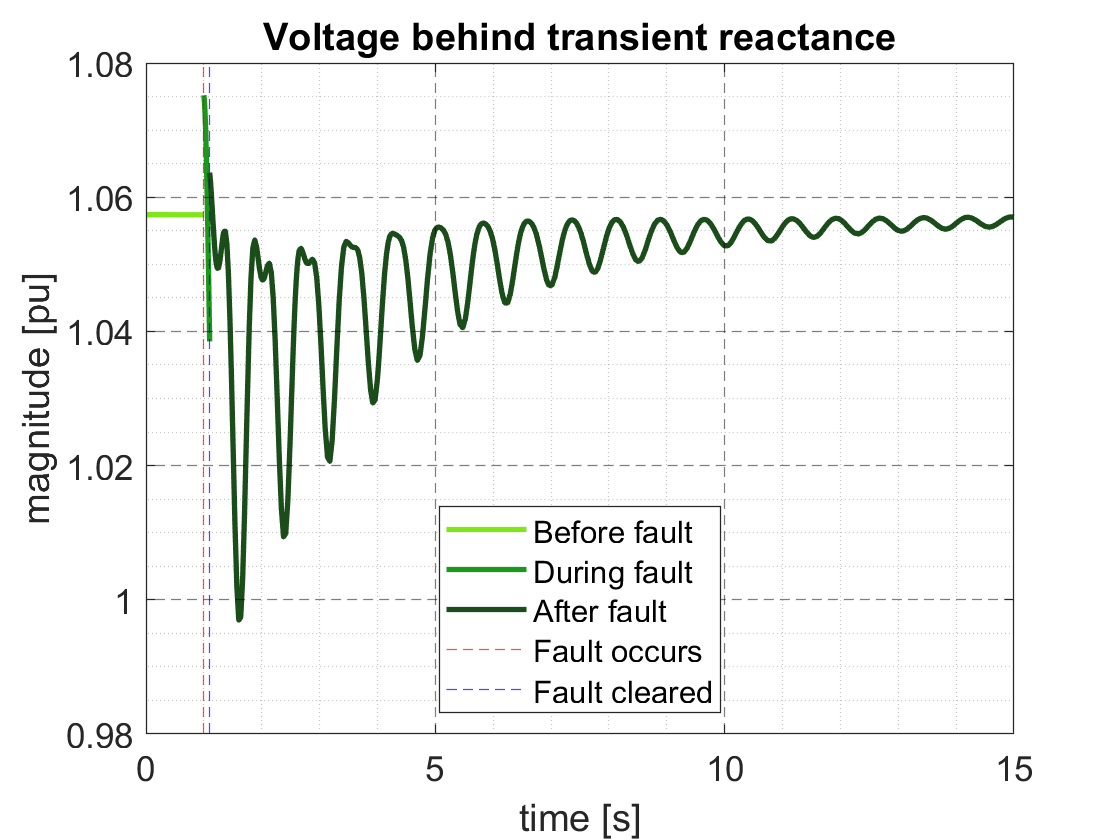

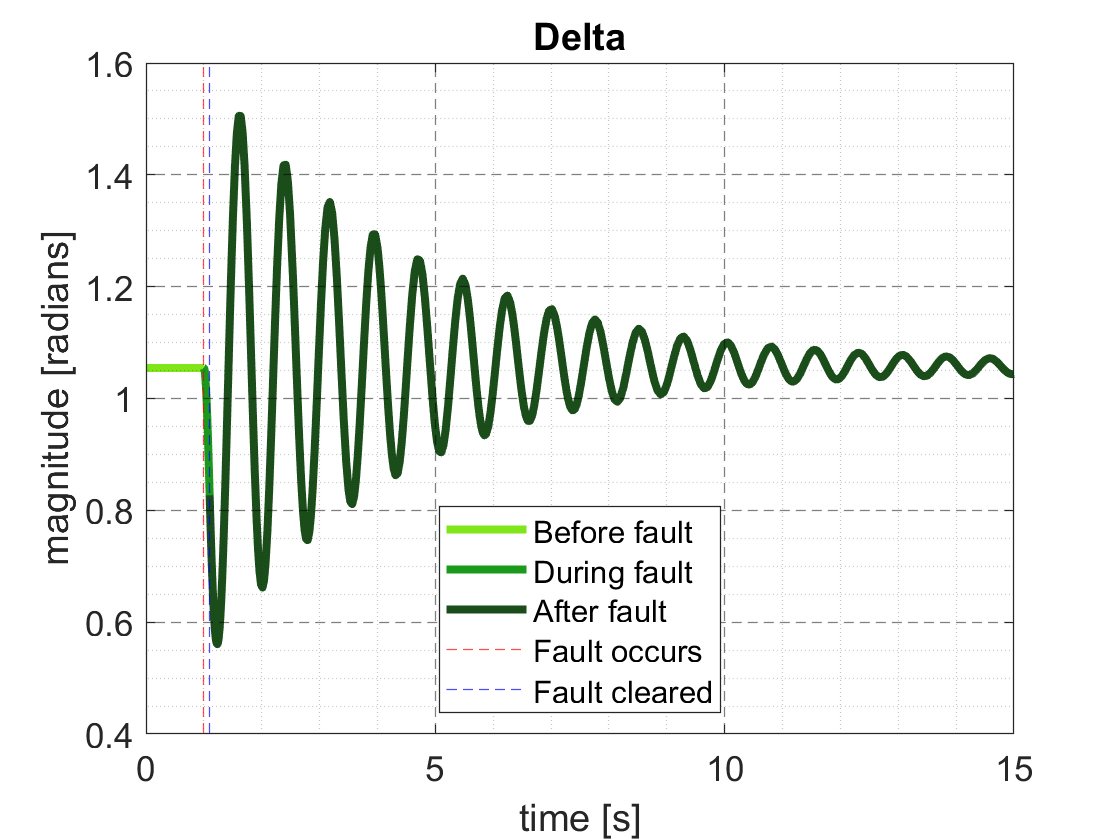

a4_07_plotResults